## **AERO95002 Numerical Analysis 2019-2020**

## **Coursework 1**

## **Dr. Elnaz Naghibi**

## **Due Date: 17 February 2020**

### **Question 1 [15%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its roots using MATLAB functions.

Explore the four methods of root finding discussed in the lecture notes and select an efficient method to find each root. Discuss your rationale and provide the code presenting the most efficient method for each root. Show the convergence to each root using appropriate plots. Finally, compare the number of iterations required to obtain each root and discuss the reason behind the difference in convergence rates of the two roots.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

Newton-Raphson is the most efficient method in finding the roots. The mid-point method can only get one root as there is no sign change before and after the root on the x-axis. For the fixed-point method here it is not a good method as the function here is quite complex. The use of fixed-point method will take a huge amount of time.

Discussion about the number of convergence. The convergences of 2 roots depend on the selection of initial point. When comparing Newton's method an Secant method, they are generally the same, the difference is that Newton's method used differential and original function to do the convergence with one intial guess while Secant method needs 2 initial guesses. It is easier to for Newton's method to be used in various functions and dimension. Also, Newton Method is faster as it converges faster. Thus, Newton Method is used in this section.

For the iterations used to obtain the 2 roots. The iteration used in first root, 1.571 is smaller

 as it can be observed from the graph. As newton method uses slope to converge to the root, the bigger slope near root 1.571 is bigger, which makes fewer iterations to acheive find the root. The gradient near root 0 is smaller, which takes more iterations to approach the correct value.

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.
%%coded by Jiaxuan Tang; CID:01486551;
%Question1;


clear
clc

x = -pi/4:0.01:pi*3/4;
%plot the diagram
syms xval;
fx1 = cos(xval).*(exp(2.*xval)-2.*exp(xval)+1);
roots = solve(fx1,xval);
disp(roots);

$$\left(\begin{array}{c} \frac{\pi }{2}\\ 0 \end{array}\right)$$

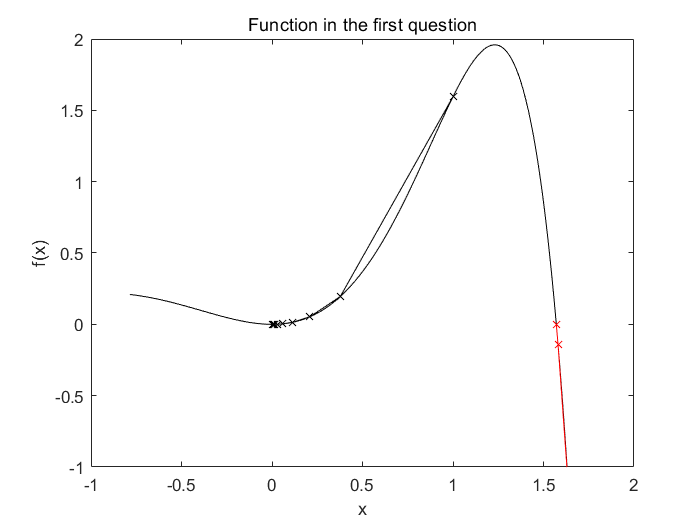

%use newton method
plot(x,fx(x),'-k');
hold on;

ylim([-1 2]);
tolerance = 0.000000001;

x0 = 2;
count1=0;
converg1=[];
xData1=[];
while abs(fx(x0)) > tolerance
    converg1 = [converg1,fx(x0)];
    xData1=[xData1,x0];
    x1 = x0 - fx(x0)/fbarX(x0);
    x0 = x1;
    count1 = count1 +1;
    hold on
end
plot(xData1,converg1,'-xr');

x0_2 =1;
count2 = 0;
converg2=[];
xData2=[];
while abs(fx(x0_2)) > tolerance
    converg2 = [converg2,fx(x0_2)];
    xData2=[xData2,x0_2];
    x1_2 = x0_2 - fx(x0_2)/fbarX(x0_2);
    x0_2 = x1_2;
    count2 = count2 + 2;
    hold on
end
title("Function in the first question");
xlabel("x");
ylabel("f(x)");
plot(xData2,converg2,'-xk');
hold off;


disp("The iterations used to find root 1.571");

The iterations used to find root 1.571


disp(count1);

     6



disp("The iterations used to find root 0");

The iterations used to find root 0


disp(count2);

    30




fprintf('The root of this function calculated is %4.3f and %4.3f.',x0,x0_2);

The root of this function calculated is 1.571 and 0.000.


disp("Below are the roots of this equation using matlab function")

Below are the roots of this equation using matlab function


disp(roots(1));%this is the analytical 1st root

$$\frac{\pi }{2}$$

disp(roots(2));%this is the analytical 2nd root

$$0$$

### **Question 2 [30%]**

**Part a:  [15 %]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of $\int_{-1}^2 \left({\textrm{ax}}^9 +{\textrm{bx}}^4 +\textrm{cx}\right)\;\textrm{dx}$ and show that it will be the same as its analytical value.

**Answer:**

%%Question 2a

clear
clc

N=5;
syms x;
Ln=1./(2.^N.*factorial(N)).*diff((x.^2-1).^N,N);
disp("This is the calculated equation of legendre polynomial:");

This is the calculated equation of legendre polynomial:


disp(simplify(Ln));

$$\frac{x\,\left(63\,x^{4}-70\,x^{2}+15\right)}{8}$$

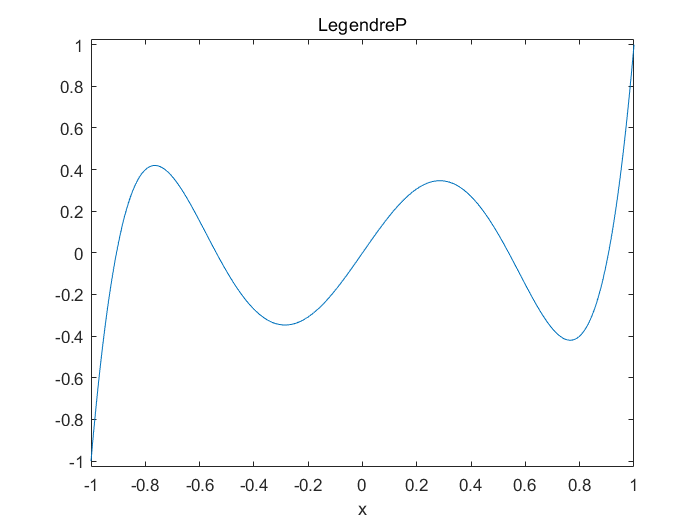


%plot the graph of Ln over x
ezplot(Ln,[-1,1]);
title("LegendreP")

%use matlab internal functions
LnM = legendreP(5,x);
disp("This is the equation of legendre polynomial using matlab function:");

This is the equation of legendre polynomial using matlab function:


disp(LnM);

$$\frac{63\,x^{5}}{8}-\frac{35\,x^{3}}{4}+\frac{15\,x}{8}$$

%solve the integral of the equation
%using t to substitute x,(2x-1)/3

%get roots
ni=solve(Ln,x);
%ni calculated(roots of the ln equation)
disp(ni);

$$\left(\begin{array}{c} 0\\ -\sqrt{\frac{5}{9}-\frac{2\,\sqrt{2}\,\sqrt{35}}{63}}\\ -\sqrt{\frac{2\,\sqrt{2}\,\sqrt{35}}{63}+\frac{5}{9}}\\ \sqrt{\frac{5}{9}-\frac{2\,\sqrt{2}\,\sqrt{35}}{63}}\\ \sqrt{\frac{2\,\sqrt{2}\,\sqrt{35}}{63}+\frac{5}{9}} \end{array}\right)$$

wi = 2./(1-(ni).^2)*(diff(Ln,1)).^(-2);%calculate the weigh coefficient
valWi=[];

for i=1:5
    valWi(i) = subs(wi(i),x,ni(i));%substituteni to get weight coefficients
end
fprintf('The weight coefficient is %3.3f ;\n',valWi);

The weight coefficient is 0.569 ;
The weight coefficient is 0.479 ;
The weight coefficient is 0.237 ;
The weight coefficient is 0.479 ;
The weight coefficient is 0.237 ;


fprintf('The root is %3.4f respectively ;\n',ni);

The root is 0.0000 respectively ;
The root is -0.5385 respectively ;
The root is -0.9062 respectively ;
The root is 0.5385 respectively ;
The root is 0.9062 respectively ;


%calculate the integration
dy = (valWi*fx2A(x2t(ni))).*3/2;


disp("This is the calculated integral:");

This is the calculated integral:


disp(vpa(simplify(dy)));

$$102.29999999999999900757950214508\,a+6.5999999999999999635806461558196\,b+1.5000000000000000003700743415417\,c$$


%calculate the analytical value
syms a b c x;
fun = a.*x.^9 + b.*x.^4 + c.*x;
intEqn = int(fun,-1,2);
%intEqn = integral(funIntegral,-1,2);

disp("The analytical one is:");

The analytical one is:


disp(intEqn);

$$\frac{1023\,a}{10}+\frac{33\,b}{5}+\frac{3\,c}{2}$$

%%intEqn == dy;

**Part b: [15 %]**

Use mid-point, trapezium and Simpson integration schemes to calculate the below integrals for $n=25,50,100,200$ and provide the code for each method accordingly.


$$\int_0^{3\pi } \textrm{sinx}\;\textrm{dx}$$



$$\int_0^{3\pi } \left|\textrm{sinx}\right|\;\textrm{dx}$$



$$\int_0^{3\pi } \sin^2 x\;\textrm{dx}$$


Calculate the errors for every value of $n$ using analytical values of integration and list the order of accuracy of the schemes as you double $n$ in each round. Compare your calculated orders of accuracy with theoretical values in chapter 3.2 of the text book "‘Fundamentals of Engineering Numerical Analysis". Discuss how different choices of integrand functions can affect the order of accuracy in the numerical schemes. 

**Answer:**

%%question 2b
clear
clc

%change n in each iteration
n=[25,50,100,200];

%initialize the integral
IntSinMid = zeros(4,1);
IntAbsSinMid = zeros(4,1);
IntSin2Mid = zeros(4,1);

IntAbsSinTrapz = zeros(4,1);
IntSinTrapz = zeros(4,1);
IntSin2Trapz = zeros(4,1);

IntSinSim = zeros(4,1);
IntAbsSinSim = zeros(4,1);
IntSin2Sim = zeros(4,1);


%mid-point rule;
for num = 1:4
    h1(num) = 3*pi/n(num);

    for i = 0:n(num)-1
        xmi(num) = 0 + h1(num)*((2*i + 1)/2);
    
        IntSinMid(num) = IntSinMid(num) + h1(num)*sin(xmi(num));
        IntAbsSinMid(num) = IntAbsSinMid(num) + h1(num)*abs(sin(xmi(num)));
        IntSin2Mid(num) = IntSin2Mid(num) + h1(num)*sin(xmi(num))^2;
    
    end

    %Trapezium rule
    xi=zeros(4,1);

    for i = 1:n(num)
        xi(num, i+1) = 0 + i*h1(num);
    end

    for i = 1:n(num)
        IntSinTrapz(num) = IntSinTrapz(num) + h1(num)*((sin(xi(num,i)) + sin(xi(num,i+1)))/2);
        IntAbsSinTrapz(num) = IntAbsSinTrapz(num) + h1(num)*((abs(sin(xi(num,i))) + abs(sin(xi(num,i+1))))/2);
        IntSin2Trapz(num) = IntSin2Trapz(num) + h1(num)*((sin(xi(num,i))^2 + sin(xi(num,i+1))^2)/2);
    end

    %simpson rule
    for i = 0:n(num)
        if mod(i,2) == 0
            if (i==0) || (i==n(num))
                IntSinSim(num) = IntSinSim(num) + sin(xi(num,i+1));
                IntAbsSinSim(num) = IntAbsSinSim(num) + abs(sin(xi(num,i+1)));
                IntSin2Sim(num) = IntSin2Sim(num) + sin(xi(num,i+1))^2;
            else
                IntSinSim(num) = IntSinSim(num) + 2*sin(xi(num,i+1));
                IntAbsSinSim(num) = IntAbsSinSim(num) + 2*abs(sin(xi(num,i+1)));
                IntSin2Sim(num) = IntSin2Sim(num) + 2*sin(xi(num,i+1))^2;
            end
    
        else
            IntSinSim(num) = IntSinSim(num) + 4*sin(xi(num,i+1));
            IntAbsSinSim(num) = IntAbsSinSim(num) + 4*abs(sin(xi(num,i+1)));
            IntSin2Sim(num) = IntSin2Sim(num) + 4*sin(xi(num,i+1))^2;
        end
    end
    IntSinSim(num) = h1(num)/3*IntSinSim(num);
    IntAbsSinSim(num) = h1(num)/3*IntAbsSinSim(num);
    IntSin2Sim(num) = h1(num)/3*IntSin2Sim(num);

end

enum = 4;%can be changed
fun1 = @(x) sin(x);
IntAnalyticalSin = integral(fun1,0,3*pi);

fun2 = @(x) abs(sin(x));
IntAnalyticalAbsSin = integral(fun2,0,3*pi);
IntAnalyticalAbsSin = 6;

fun3 = @(x) sin(x).^2;
IntAnalyticalSin2 = integral(fun3,0,3*pi);

%Simpson method for n=25 Doesn't exist;
%calculation of error for each n here
errorFun1Mid25 = -IntSinMid(1) + IntAnalyticalSin

errorFun1Mid25 = -0.0119

errorFun1Sim25 = -IntSinSim(1) + IntAnalyticalSin

errorFun1Sim25 = 0.0237

errorFun1Trapz25 = -IntSinTrapz(1) + IntAnalyticalSin

errorFun1Trapz25 = 0.0237


errorFun2Mid25 = -IntAbsSinMid(1) + IntAnalyticalAbsSin

errorFun2Mid25 = -0.0039

errorFun2Sim25 = -IntAbsSinSim(1) + IntAnalyticalAbsSin

errorFun2Sim25 = 0.0079

errorFun2Trapz25 = -IntAbsSinTrapz(1) + IntAnalyticalAbsSin

errorFun2Trapz25 = 0.0079


errorFun3Mid25 = -IntSin2Mid(1) + IntAnalyticalSin2

errorFun3Mid25 = -1.7764e-15

errorFun3Sim25 = -IntSin2Sim(1) + IntAnalyticalSin2

errorFun3Sim25 = 0

errorFun3Trapz25 = -IntSin2Trapz(1) + IntAnalyticalSin2

errorFun3Trapz25 = -8.8818e-16



errorFun1Mid50 = -IntSinMid(2) + IntAnalyticalSin

errorFun1Mid50 = -0.0030

errorFun1Sim50 = -IntSinSim(2) + IntAnalyticalSin

errorFun1Sim50 = -1.4086e-05

errorFun1Trapz50 = -IntSinTrapz(2) + IntAnalyticalSin

errorFun1Trapz50 = 0.0059


errorFun2Mid50 = -IntAbsSinMid(2) + IntAnalyticalAbsSin

errorFun2Mid50 = -9.8707e-04

errorFun2Sim50 = -IntAbsSinSim(2) + IntAnalyticalAbsSin

errorFun2Sim50 = -5.1976e-07

errorFun2Trapz50 = -IntAbsSinTrapz(2) + IntAnalyticalAbsSin

errorFun2Trapz50 = 0.0020


errorFun3Mid50 = -IntSin2Mid(2) + IntAnalyticalSin2

errorFun3Mid50 = -1.7764e-15

errorFun3Sim50 = -IntSin2Sim(2) + IntAnalyticalSin2

errorFun3Sim50 = -8.8818e-16

errorFun3Trapz50 = -IntSin2Trapz(2) + IntAnalyticalSin2

errorFun3Trapz50 = -1.7764e-15



errorFun1Mid100 = -IntSinMid(3) + IntAnalyticalSin

errorFun1Mid100 = -7.4041e-04

errorFun1Sim100 = -IntSinSim(3) + IntAnalyticalSin

errorFun1Sim100 = -8.7761e-07

errorFun1Trapz100 = -IntSinTrapz(3) + IntAnalyticalSin

errorFun1Trapz100 = 0.0015


errorFun2Mid100 = -IntAbsSinMid(3) + IntAnalyticalAbsSin

errorFun2Mid100 = -2.4675e-04

errorFun2Sim100 = -IntAbsSinSim(3) + IntAnalyticalAbsSin

errorFun2Sim100 = -3.2474e-08

errorFun2Trapz100 = -IntAbsSinTrapz(3) + IntAnalyticalAbsSin

errorFun2Trapz100 = 4.9349e-04


errorFun3Mid100 = -IntSin2Mid(3) + IntAnalyticalSin2

errorFun3Mid100 = -8.8818e-16

errorFun3Sim100 = -IntSin2Sim(3) + IntAnalyticalSin2

errorFun3Sim100 = -2.6645e-15

errorFun3Trapz100 = -IntSin2Trapz(3) + IntAnalyticalSin2

errorFun3Trapz100 = -1.7764e-15



errorFun1Mid200 = -IntSinMid(4) + IntAnalyticalSin

errorFun1Mid200 = -1.8507e-04

errorFun1Sim200 = -IntSinSim(4) + IntAnalyticalSin

errorFun1Sim200 = -5.4807e-08

errorFun1Trapz200 = -IntSinTrapz(4) + IntAnalyticalSin

errorFun1Trapz200 = 3.7012e-04


errorFun2Mid200 = -IntAbsSinMid(4) + IntAnalyticalAbsSin

errorFun2Mid200 = -6.1685e-05

errorFun2Sim200 = -IntAbsSinSim(4) + IntAnalyticalAbsSin

errorFun2Sim200 = -2.0294e-09

errorFun2Trapz200 = -IntAbsSinTrapz(4) + IntAnalyticalAbsSin

errorFun2Trapz200 = 1.2337e-04


errorFun3Mid200 = -IntSin2Mid(4) + IntAnalyticalSin2

errorFun3Mid200 = 0

errorFun3Sim200 = -IntSin2Sim(4) + IntAnalyticalSin2

errorFun3Sim200 = -2.6645e-15

errorFun3Trapz200 = -IntSin2Trapz(4) + IntAnalyticalSin2

errorFun3Trapz200 = -1.7764e-15



%calculation of order of accuracy using array to store
orderOfAccuracy_1Mid(1) = log2((errorFun1Mid25/errorFun1Mid50))

orderOfAccuracy_1Mid = 2.0045

orderOfAccuracy_1Mid(2) = log2((errorFun1Mid50/errorFun1Mid100))

orderOfAccuracy_1Mid =     2.0045    2.0011


orderOfAccuracy_1Mid(3) = log2((errorFun1Mid100/errorFun1Mid200))

orderOfAccuracy_1Mid =     2.0045    2.0011    2.0003



orderOfAccuracy_2Mid(1) = log2((errorFun2Mid25/errorFun2Mid50))

orderOfAccuracy_2Mid = 2.0005

orderOfAccuracy_2Mid(2) = log2((errorFun2Mid50/errorFun2Mid100))

orderOfAccuracy_2Mid =     2.0005    2.0001


orderOfAccuracy_2Mid(3) = log2((errorFun2Mid100/errorFun2Mid200))

orderOfAccuracy_2Mid =     2.0005    2.0001    2.0000



orderOfAccuracy_3Mid(1) = log2((errorFun3Mid25/errorFun3Mid50))

orderOfAccuracy_3Mid = 0

orderOfAccuracy_3Mid(2) = log2((errorFun3Mid50/errorFun3Mid100))

orderOfAccuracy_3Mid =      0     1


orderOfAccuracy_3Mid(3) = log2((errorFun3Mid100/errorFun3Mid200))

orderOfAccuracy_3Mid =    0.0000 + 0.0000i   1.0000 + 0.0000i      Inf + 4.5324i




orderOfAccuracy_1Trapz(1) = log2((errorFun1Trapz25/errorFun1Trapz50))

orderOfAccuracy_1Trapz = 2.0026

orderOfAccuracy_1Trapz(2) = log2((errorFun1Trapz50/errorFun1Trapz100))

orderOfAccuracy_1Trapz =     2.0026    2.0006


orderOfAccuracy_1Trapz(3) = log2((errorFun1Trapz100/errorFun1Trapz200))

orderOfAccuracy_1Trapz =     2.0026    2.0006    2.0002



orderOfAccuracy_2Trapz(1) = log2((errorFun2Trapz25/errorFun2Trapz50))

orderOfAccuracy_2Trapz = 2.0003

orderOfAccuracy_2Trapz(2) = log2((errorFun2Trapz25/errorFun2Trapz50))

orderOfAccuracy_2Trapz =     2.0003    2.0003


orderOfAccuracy_2Trapz(3) = log2((errorFun2Trapz25/errorFun2Trapz50))

orderOfAccuracy_2Trapz =     2.0003    2.0003    2.0003



orderOfAccuracy_3Trapz(1) = log2((errorFun3Trapz25/errorFun3Trapz50))

orderOfAccuracy_3Trapz = -1

orderOfAccuracy_3Trapz(2) = log2((errorFun3Trapz50/errorFun3Trapz100))

orderOfAccuracy_3Trapz =     -1     0


orderOfAccuracy_3Trapz(3) = log2((errorFun3Trapz100/errorFun3Trapz200))

orderOfAccuracy_3Trapz =     -1     0     0




orderOfAccuracy_1Sim(1) = log2((errorFun1Sim25/errorFun1Sim50))

orderOfAccuracy_1Sim = 10.7190 + 4.5324i

orderOfAccuracy_1Sim(2) = log2((errorFun1Sim50/errorFun1Sim100))

orderOfAccuracy_1Sim =   10.7190 + 4.5324i   4.0046 + 0.0000i


orderOfAccuracy_1Sim(3) = log2((errorFun1Sim100/errorFun1Sim200))

orderOfAccuracy_1Sim =   10.7190 + 4.5324i   4.0046 + 0.0000i   4.0011 + 0.0000i



orderOfAccuracy_2Sim(1) = log2((errorFun2Sim25/errorFun2Sim50))

orderOfAccuracy_2Sim = 13.8913 + 4.5324i

orderOfAccuracy_2Sim(2) = log2((errorFun2Sim50/errorFun2Sim100))

orderOfAccuracy_2Sim =   13.8913 + 4.5324i   4.0005 + 0.0000i


orderOfAccuracy_2Sim(3) = log2((errorFun2Sim100/errorFun2Sim200))

orderOfAccuracy_2Sim =   13.8913 + 4.5324i   4.0005 + 0.0000i   4.0001 + 0.0000i



orderOfAccuracy_3Sim(1) = log2((errorFun3Sim25/errorFun3Sim50))

orderOfAccuracy_3Sim = -Inf

orderOfAccuracy_3Sim(2) = log2((errorFun3Sim50/errorFun3Sim100))

orderOfAccuracy_3Sim =       -Inf   -1.5850


orderOfAccuracy_3Sim(3) = log2((errorFun3Sim100/errorFun3Sim200))

orderOfAccuracy_3Sim =       -Inf   -1.5850         0




disp("The integral profile is below:");

The integral profile is below:


disp(IntSinMid);

    2.0119
    2.0030
    2.0007
    2.0002



disp(IntSinTrapz);

    1.9763
    1.9941
    1.9985
    1.9996



disp(IntSinSim);

    1.9763
    2.0000
    2.0000
    2.0000



disp(IntAbsSinTrapz);

    5.9921
    5.9980
    5.9995
    5.9999



disp(IntAbsSinSim);

    5.9921
    6.0000
    6.0000
    6.0000



disp(IntAbsSinMid);

    6.0039
    6.0010
    6.0002
    6.0001



disp(IntSin2Trapz);

    4.7124
    4.7124
    4.7124
    4.7124



disp(IntSin2Sim);

    4.7124
    4.7124
    4.7124
    4.7124



disp(IntSin2Mid);

    4.7124
    4.7124
    4.7124
    4.7124





disp("for enum = 4, n = 200");

for enum = 4, n = 200


fprintf('The intergral of sinx using mid-point rule is %3.3f',IntSinMid(enum));

The intergral of sinx using mid-point rule is 2.000

fprintf('The intergral of abs sinx using mid-point rule is %3.3f',IntAbsSinMid(enum));

The intergral of abs sinx using mid-point rule is 6.000

fprintf('The intergral of sinx^2 using mid-point rule is %3.3f',IntSin2Mid(enum));

The intergral of sinx^2 using mid-point rule is 4.712


fprintf('The integral of sinx using tapz is %3.3f',IntSinTrapz(enum));

The integral of sinx using tapz is 2.000

fprintf('The integral of abs sinx using tapz is %3.3f',IntAbsSinTrapz(enum));

The integral of abs sinx using tapz is 6.000

fprintf('The integral of sinx ^ 2 using tapz is %3.3f',IntSin2Trapz(enum));

The integral of sinx ^ 2 using tapz is 4.712


fprintf('The integral of sinx using simpson is %3.3f',IntSinSim(enum));

The integral of sinx using simpson is 2.000

fprintf('The integral of abs sinx using simpson is %3.3f',IntAbsSinSim(enum));

The integral of abs sinx using simpson is 6.000

fprintf('The integral of sinx ^ 2 using simpson is %3.3f',IntSin2Sim(enum));

The integral of sinx ^ 2 using simpson is 4.712

Below is the table according to the data calculated:

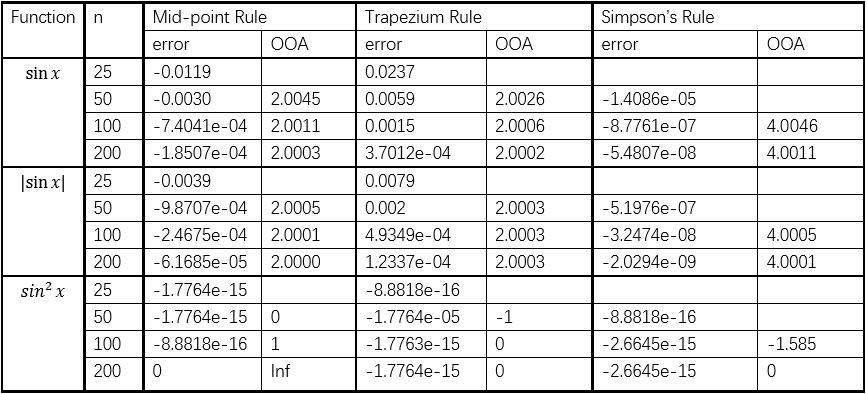

For the order of accuracy calculated in this table. When comparing with values on textbook,it can be observed that the values for function sin(x) and |sin(x)| using mid-point rule are almost with value equal to 2 here. It is also the same condition for the trapezium rule used in both sinx and |sinx|. Both of the 2 functions generate order of accuracy of 2 here. The textbook mentioned that the order of accuracy of Simpson's rule is 4. From the table, it can be seen that for sinx and |sinx|, they have the order of accurcay through the column, which proves the validity of the code. It should be noticed that theoretically the order of accuracy should always be integer. The reason that these calculated numbers are not integers is mainly contributed by the accuracy of matlab calculation, very small difference can cause huge error on the value of order of accuracy.

When Looking at the order of accuracy for the equation $\sin {\left(x\right)}^2$,all of them are not the same as the values on the textbook. The existence of inf means the error for that integration is zero and when order of accuracy is 0, it generally means the error has the same error. For Simpson's rule and trapezium rule applying on this function, negative values appeared, which implies the error of the integration increases by the double of n. As a result, the  $\sin {\left(x\right)}^2$ function is not a good reference proving order of accuracy.

### **Question 3 [25%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -2,2\right\rbrack$. Write a code to calculate the cubic spline passing though these points. Increase the number of points to 15 and rebuild the cubic spline. Compare your results with equally-spaced arrays of function values for n=5 and n=15 and report the Euclidean norm of error in each case.

**Answer:**

clear
clc

%chebyshev
%n reprensents n of points;
disp("using 1000 points");

using 1000 points


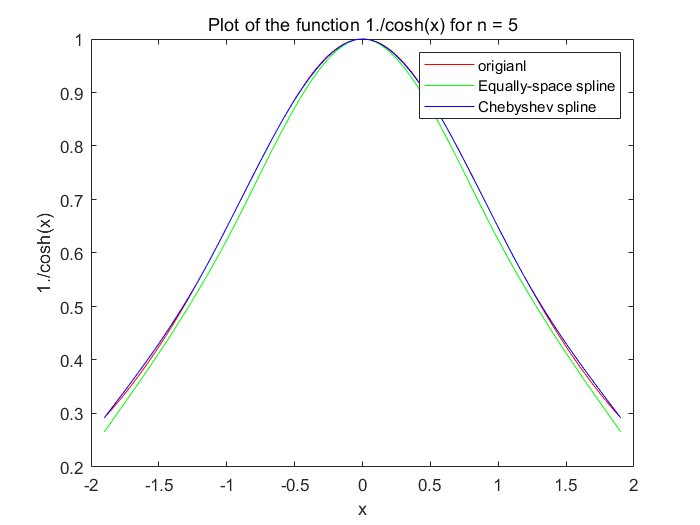



n=5;
N=n-1;
i=0:1:N;
x = chebyshev(N,i).*2;
xEven=[-2,-1,0,1,2];
%in the interval -2:2
%using cubic spline
y=1./cosh(x);
coeff = CubicSpline(x,y);
coeffEven = CubicSpline(xEven,1./cosh(xEven));
%number of rows N means intervals
xval = linspace(x(1),x(n),1000);
xvalEven=linspace(-2,2,1000);
for i = 1:length(xval)
   yVal(i)=cubicEval(x,coeff,xval(i));
   yValEven(i)=cubicEval(xEven,coeffEven,xvalEven(i));
end

plot(xval,1./cosh(xval),'r');%plot the original function
hold on
plot(xval,yValEven,"g");%plot the equally-spaced spline function
hold on;
plot(xval,yVal,'b');%plot the chebyshev spline function
title("Plot of the function 1./cosh(x) for n = 5");
xlabel("x");
ylabel("1./cosh(x)");
legend("origianl","Equally-space spline","Chebyshev spline");
hold off;


EuNorm1 = norm(yVal-1./cosh(xval));
EuNormEven1=norm(yValEven-1./cosh(xvalEven));
%calculate the euclid norms

disp("The norm of error for chebyshev selection is(n=5): ");

The norm of error for chebyshev selection is(n=5): 


disp(EuNorm1);%print the euclidean for chebyshev spline n=5

    0.0913



disp("The norm of error for equally-space is(n=5):")

The norm of error for equally-space is(n=5):


disp(EuNormEven1);%print the euclidean for equally-space splines n=5

    0.2734



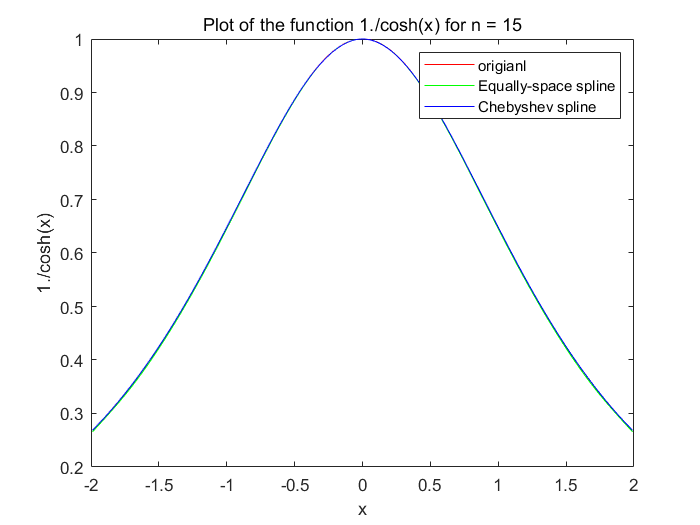



clear 
clc

n=15;
N=n-1;
i=0:1:N;
x2 = chebyshev(N,i).*2;
xEven2=linspace(-2,2,15);
%in the interval -2:2
%using cubic spline
y2=1./cosh(x2);
coeff2 = CubicSpline(x2,y2);
coeffEven2=CubicSpline(xEven2,1./cosh(xEven2));
%number of rows N means intervals

xval2 = linspace(x2(1),x2(n),1000);
xvalEven2=linspace(-2,2,1000);
for i = 1:length(xval2)
   yVal2(i)=cubicEval(x2,coeff2,xval2(i));
   yValEven2(i)=cubicEval(xEven2,coeffEven2,xvalEven2(i)); 
end

plot(xval2,1./cosh(xval2),'r');%This is the orginal plot
hold on
plot(xval2,yValEven2,'g');%Equally-spaced spline
hold on
plot(xval2,yVal2,'b');%chebyshev spline
title("Plot of the function 1./cosh(x) for n = 15");
xlabel("x");
ylabel("1./cosh(x)");
legend("origianl","Equally-space spline","Chebyshev spline");
hold off;


EuNorm2 = norm(yVal2-1./cosh(xval2));
EuNormEven2=norm(yValEven2-(1./cosh(xvalEven2)));
%calculate the euclid norms
disp("The norm of error for chebyshev selection is(n=15): ");

The norm of error for chebyshev selection is(n=15): 


disp(EuNorm2);%euclidean norm for the chebyshev splinen=15

    0.0048



disp("The norm of error for equally-space is(n=15):")

The norm of error for equally-space is(n=15):


disp(EuNormEven2);%euclidean norm for the equally-space spline n=15

    0.0080



### **Question 4 [30%]**

**Part a: [15 %]**

Using the MATLAB command "meshgrid", create a $100\;\times \;100$ grid on the interval $x,y$$\in \left\lbrack -1,1\right\rbrack$. Create the discretized values of the function $f\left(x,y\right)=x^3 +3{\textrm{yx}}^2$ in this interval. Calculate 2D distributions of $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ using finite difference schemes (use central difference for interior points and forward/backward difference for the points on the boundary). Plot the numerically calculated profiles of  $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ on planes$x=0$ and $y=0\ldotp 5$and compare them with the analytical profiles of the derivatives.

**Answer:**

clear
clc

x(1,:)=[-1:0.02:1];
y(:,1)=[-1:0.02:1];
[xmesh,ymesh] = meshgrid(x,y);
%xmesh, x changes with colums, rows are the same;
%ymesh, y changes with rows, colums are the same;

diffx=zeros(101);
diffy=zeros(101);
for j=1:101
   for i=2:100
        diffx(j,i) = (fx4(xmesh(j,i+1),ymesh(j,i-1))-fx4(xmesh(j,i-1),ymesh(j,i-1)))/0.04;    
        diffy(i,j) = (fx4(xmesh(i,j),ymesh(i+1,j))-fx4(xmesh(i,j),ymesh(i-1,j)))/0.04;
   end
end
%diffx, x changes along columns
%diffx, y changes along rows;

%forward difference
diffx(:,1)=(fx4(xmesh(:,2),ymesh(:,2))-fx4(xmesh(:,1),ymesh(:,1)))./0.02;
diffy(1,:)=(fx4(xmesh(2,:),ymesh(2,:))-fx4(xmesh(1,:),ymesh(1,:)))./0.02;
%backward difference
diffx(:,101)=(fx4(xmesh(:,101),ymesh(:,101))-fx4(xmesh(:,100),ymesh(:,100)))./0.02;
diffx(101,:)=(fx4(xmesh(101,:),ymesh(101,:))-fx4(xmesh(100,:),ymesh(100,:)))./0.02;


disp("The 2d distribution of df/dx and df/dy is:");

The 2d distribution of df/dx and df/dy is:


disp(diffx);

  列 1 至 14

    8.8804    8.7616    8.5252    8.2912    8.0596    7.8304    7.6036    7.3792    7.1572    6.9376    6.7204    6.5056    6.2932    6.0832
    8.7616    8.6440    8.4100    8.1784    7.9492    7.7224    7.4980    7.2760    7.0564    6.8392    6.6244    6.4120    6.2020    5.9944
    8.6428    8.5264    8.2948    8.0656    7.8388    7.6144    7.3924    7.1728    6.9556    6.7408    6.5284    6.3184    6.1108    5.9056
    8.5240    8.4088    8.1796    7.9528    7.7284    7.5064    7.2868    7.0696    6.8548    6.6424    6.4324    6.2248    6.0196    5.8168
    8.4052    8.2912    8.0644    7.8400    7.6180    7.3984    7.1812    6.9664    6.7540    6.5440    6.3364    6.1312    5.9284    5.7280
    8.2864    8.1736    7.9492    7.7272    7.5076    7.2904    7.0756    6.8632    6.6532    6.4456    6.2404    6.0376    5.8372    5.6392
    8.1676    8.0560    7.8340    7.6144    7.3972    7.1824    6.9700    6.7600    6.5524    6.3472    6.1444    5.9440    5.7460    5.5504
 

disp(diffy);

  列 1 至 14

    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
    3.0000    2.8812    2.7648    2.6508    2.5392    2.4300    2.3232    2.2188    2.1168    2.0172    1.9200    1.8252    1.7328    1.6428
 

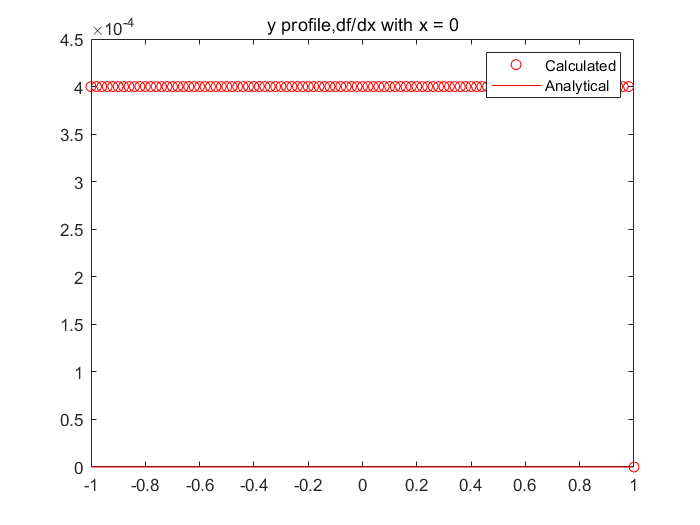


%This is the analytical integral solution.
diffxA = fx4Odx(xmesh,ymesh);
diffyA = fx4Ody(xmesh,ymesh);

%x=0 fixed,i=51;y=0.5 fixed,j=76
plot(y,diffx(:,51),'or');
hold on
title("y profile,df/dx with x = 0");
plot(y,diffxA(:,51),'-r');
legend("Calculated","Analytical");
hold off

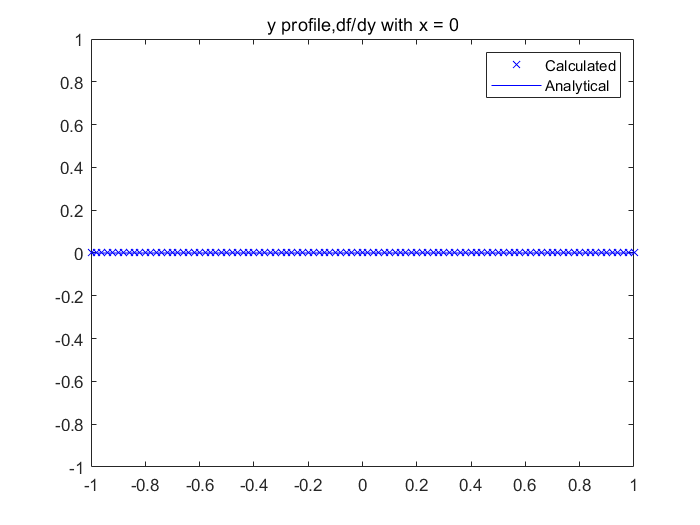


plot(y,diffy(:,51),'xb');
hold on
title("y profile,df/dy with x = 0");
plot(y,diffyA(:,51),'-b');
legend("Calculated","Analytical");
hold off

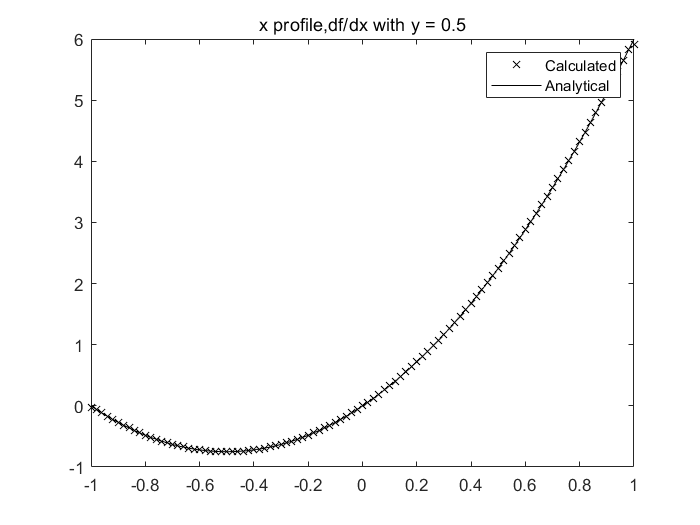


plot(x,diffx(76,:),'xk');
hold on
title("x profile,df/dx with y = 0.5");
plot(x,diffxA(76,:),'-k');
legend("Calculated","Analytical");
hold off

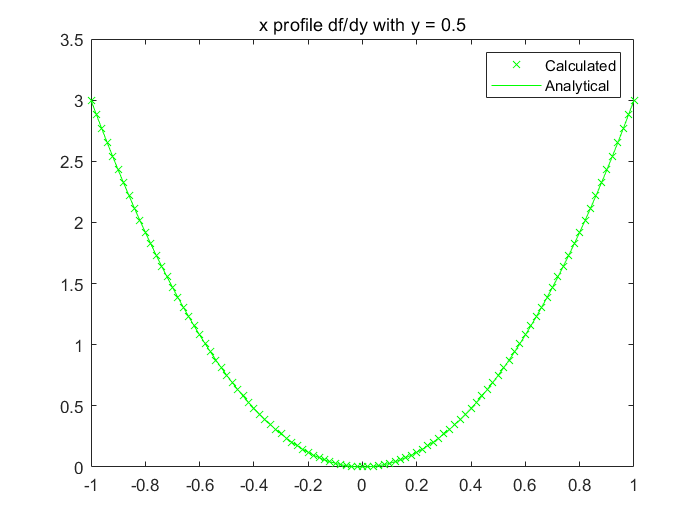


plot(x,diffy(76,:),'xg');
hold on
title("x profile df/dy with y = 0.5");
plot(x,diffyA(76,:),'-g');
legend("Calculated","Analytical");
hold off

**Part b: [15 %]**

Use the systematic method to construct the finite-difference approximation of  $\frac{{\mathrm{d}}^4 f}{\mathrm{d}x^4 }$ using the stencil $\left(-2,-1,0,1,2\right)$. Report the coefficients obtained and the order of the truncation error in this approximation. Comment under which circumstance this approximation will provide an exact solution.

**Answer:**

%sampling = [-2,-1,0,1,2];
stencil = [-2,-1,0,1,2];
%finite-difference approximation

Get the taylor series expansion and stencil = [-2, -1, 0, 1, 2];

$\frac{d^{j} f}{d x^{j}}\left(x_{i}\right)=\sum_{k=-M}^{k=N} a_{k} f_{i+k}+\epsilon_{t r u n c}$;

$\frac{d^{4} f}{d x^{4}}\left(x_{i}\right)=a_{-2} f_{i-2}+a_{-1} f_{i-1}+a_{0} f_{i}+a_{1} f_{i+1}+a_{2} f+\epsilon_{t r u n c}$;


$$\frac{d^4 f}{dx^4 }{\left(x_i \right)}=a_{-2} {\left[f_i -2f_i^{\prime } \frac{∆x}{1!}+4f_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}-8f_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+16f_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}+a_{-1} {\left[f_i -f_i^{\prime } \frac{∆x}{1!}+f_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}-f_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+f_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}+a_0 f_i +a_1 {\left[f_i +f_i^{\prime } \frac{∆x}{1!}+f_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}+f_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+f_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}\ +a_2 {\left[f_i +2f_i^{\prime } \frac{∆x}{1!}+4f_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}+8f_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+16f_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}$$


Then solve to get the coefficients.


$${\left[\begin{array}{ccccc}
1 & 1 & 1 & 1 & 1\\
-2 & -1 & 0 & 1 & 2\\
4 & 1 & 0 & 1 & 4\\
-8 & -1 & 0 & 1 & 8\\
16 & 1 & 0 & 1 & 16
\end{array}\right]}{\left[\begin{array}{c}
a_{-2} \\
a_{-1} \\
a_0 \\
a_1 \\
a_2 
\end{array}\right]}={\left[\begin{array}{c}
0\\
0\\
0\\
0\\
\frac{4!}{\left(\textrm{∆}{\left.x\right)}^4 \right.}
\end{array}\right]}$$


Thus,


$$\frac{d^{4} f}{d x^{4}}\left(x_{i}\right)=\frac{f_{i-2}-4 f_{i-1}+6 f_{i}-4 f_{i+1}+f_{i+2}}{(\Delta x)^{4}}+\in_{\text {trunc }}$$


Therefore, the trunction error then should be: $\in_{trunc} =\frac{d^5 f}{dx^5 }{\left(x_i \right)}$

As a result, the order of the trunction error is 5. $\in_{trunc}$ should be zero. To get the exact solution, We need the sixth term of partial derivative to be 0.

Below are the functions used in this coursework

function f = fx4(x,y)
    f=x.^3+3.*y.*x.^2; 
end

function diff = fx4Odx(x,y)
    diff=3.*x.^2+6.*x.*y;
end

function diff = fx4Ody(x,y)
    diff = 3.*x.^2;
end


function y = fx(x)
 y = cos(x).*(exp(2.*x) - 2.*exp(x) + 1);
end


function dydx = fbarX(x)
 dydx = -sin(x) .*(exp(2.*x) - 2.*exp(x) + 1) + cos(x) .*(2.*exp(2.*x) - 2.*exp(x));  
end


function x=x2t(t)
    x=(3.*t+1)./2;    
end


function y = fx2A(x)
 syms a b c;
 y=a.*x.^9+b.*x.^4+c.*x;
end


function xj = chebyshev(N,i)
xj = -cos(((2.*i+1)/(2.*N+2)).*pi);
end


function polyArray=CubicSpline(x,fx)
n=length(x);%find the length of the array
m=zeros(n,1);%create the array with zeros used after as both the initial and the last values are zero
mat_h=zeros(n-2);%create the matrix for the collection of h as majority part is zero

for i=1:(n-1)
    h(i)=x(i+1)-x(i);%get the interval
end

%try to create matrix which can solve m, need to rearrange the matrix to
%make it a square matrix which has inverse
%in this occation, y is a 7X1 matrix with fi and hi with i from 2 to n-1
y(1:n-2,1)=6.*(((fx(3:n)-fx(2:n-1))./h(2:n-1)-(fx(2:n-1)-fx(1:n-2))./h(1:n-2)));%create the matrix for the f and h, which are in the equation of h and m

%the matrix for h is special create the 1 ad n-2 which contain 2 values
%each. The matrix is 7X7 with hi from 2 to n-1
mat_h(1,[1,2])=[2*(h(2)+h(1)),h(2)];
mat_h(n-2,[n-3,n-2])=[h(n-2),2*(h(n-2)+h(n-1))];%the first and the last row are special as it eliminates h1 and h8 as the m1 and mN are both zero so there are 2 values in that row
%create rows which contain 3 values each
for n2=3:n-2
    mat_h(n2-1,[(n2-2),n2-1,n2])=[h(n2-1),2*(h(n2-1)+h(n2)),h(n2)];%fill the value in the matrix with hi-1, 2*(hi-1+hi) and hi
end

%solve the m by array operations from 2 to n-1 as 1 and n are both 0
m(2:n-1,1)=mat_h\y;
%can use loops instead, but is will be more organized while array
%operations will be faster
a(1:n-1,1)=fx(1:n-1)';
b(1:n-1,1)=((fx(2:n)'-fx(1:n-1)')./h(1:n-1)')-(h(1:n-1)'.*(2.*m(1:n-1,1)+m(2:n,1))./6);%the dimensions need to be the same
c(1:n-1,1)=m(1:n-1,1)./2;
d(1:n-1,1)=(m(2:n,1)-m(1:n-1,1))./(6.*h(1:n-1)');
%fill the arguments using array operations, the dimension of each
%coefficients is (n-1)x1
polyArray=[d,c,b,a];%the output is a N-1x4 array as there are n-1 intervals

end


function yInterpVal = cubicEval(x,polyArray,xval)
n=length(x);
%%use bisection search to determine which segment the interpolation "xval"
klower = 1;
kupper = n;
%IF statement to check that xval lies within the sample data range
if (xval >= x(1) && xval <= x(n))
while (kupper - klower > 1) %continue search until search interval has reduced to two consecutive points
    kmid = ceil((klower + kupper)/2); %split domain in half and move to the half containing xval
    if (xval < x(kmid))
        kupper=kmid;
    else
        klower=kmid;
    end
end
else
    %If xval not within the x-range of the dataset print error and return
    %NaN
    disp('Error: Please enter an interpolation x-value "xval" that lies within the range of x');
    yInterpVal=NaN;
    return;
end

%use correct set of polynomials from the appropriate row in polyArray to
%evaluate polynomial using polyval() function.
yInterpVal = polyval(polyArray(klower,:),(xval-x(klower)));

end
